FileFolder = 'C:\Users\eric\Documents\_CursoMatlab\Módulo 1\SpecFiles';
FileName   = 'rfeye002119_210324_T143233_MaskBroken.bin';

File       = fullfile(FileFolder, FileName);

tic
specData   = FileReader_CRFSBin_mat2(File);
toc

Elapsed time is 1.436598 seconds.


specData(1)

ans = struct with fields:
               Node: 'RFeye002119'
           ThreadID: 301
           MetaData: [1×1 struct]
    ObservationTime: '24/03/2021 14:32:36 - 24/03/2021 16:38:20'
            Samples: 1424
               Data: {1×2 cell}
          statsData: []
         FileFormat: 'CRFS Bin v.5'
           TaskName: 'ScriptRFeye2021v.1'
        Description: 'PMEC 2021 (Faixa 1 de 10). @ -80dBm, 10kHz.'
       RelatedFiles: {'rfeye002119_210324_T143233_MaskBroken.bin'}
         RelatedGPS: {[1×1 struct]}
                gps: [1×1 struct]
             Blocks: [1424×5 table]


specData(1).MetaData

ans = struct with fields:
      DataType: 68
      ThreadID: 301
     FreqStart: 108000000
      FreqStop: 137000000
     LevelUnit: 1
    DataPoints: 14848
    Resolution: 3690
    SampleTime: []
     Threshold: -100
     TraceMode: 2
      Detector: []
    metaString: {'dBm'  '3.690 kHz'  'Peak'  ''  'CRFS RFeye (Auto)'}


specData(1).Data{1}(1:5)

ans = 1×5 datetime array
   24/03/2021 14:32:36   24/03/2021 14:32:41   24/03/2021 14:32:46   24/03/2021 14:32:51   24/03/2021 14:32:58


specData(1).Data{2}(1:5,1:5)

ans = 5×5 single matrix
  -98.0000 -100.0000  -97.5000 -100.0000 -101.0000
  -95.5000  -98.0000  -97.0000  -99.5000 -101.0000
  -97.5000 -100.0000  -99.0000  -98.0000 -101.0000
 -100.0000  -99.0000  -95.0000  -98.0000  -99.5000
  -99.0000  -98.5000 -100.0000  -96.5000  -98.5000


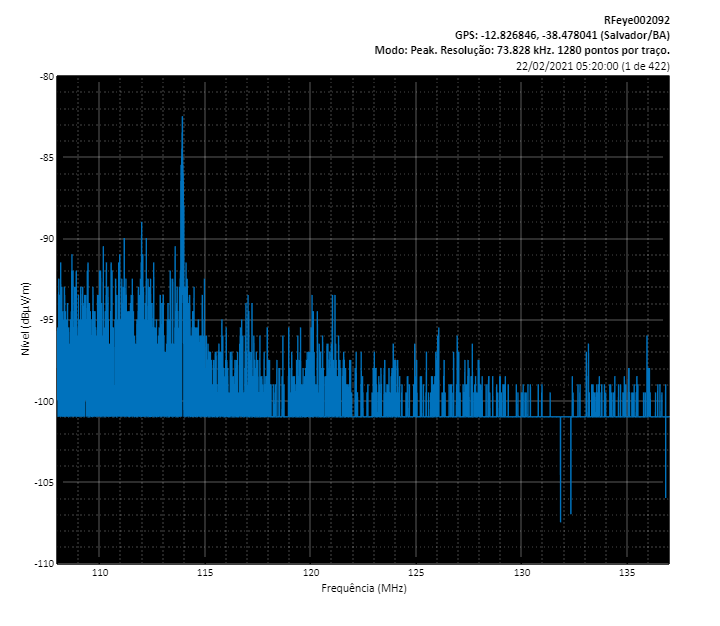

FreqStart  = specData(1).MetaData.FreqStart / 1e+6;
FreqStop   = specData(1).MetaData.FreqStop  / 1e+6;
DataPoints = specData(1).MetaData.DataPoints;

freq = linspace(FreqStart, FreqStop, DataPoints);
Module1_createfigure(freq, specData(1).Data{2}(:,1))

[minY, maxY] = bounds(specData(1).Data{2}, 'all')

minY = single
-115

maxY = single
-56

h = findobj('Tag', 'SpectralData')

h =   Line (SpectralData) with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [108 108.0020 108.0039 108.0059 108.0078 108.0098 108.0117 108.0137 108.0156 108.0176 108.0195 108.0215 108.0234 108.0254 108.0273 108.0293 108.0313 108.0332 108.0352 108.0371 108.0391 108.0410 108.0430 108.0449 108.0469 108.0488 … ]
              YData: [-98 -93 -92 -98 -99 -97.5000 -95.5000 -98.5000 -96 -94 -99 -98 -93 -93.5000 -99.5000 -98 -93.5000 -93 -97 -96.5000 -99 -100 -98 -97.5000 -95 -94 -93.5000 -95 -95 -95 -93.5000 -93 -95.5000 -98 -97 -97 -96.5000 -93.5000 -93.5000 … ]
              ZData: [1×0 double]

  Show 

set(h.Parent, 'YLim', [minY, maxY])

for ii = 1:specData(1).Samples
    h.YData = specData(1).Data{2}(:,ii);
    pause(.1)
end